# Exercise 7

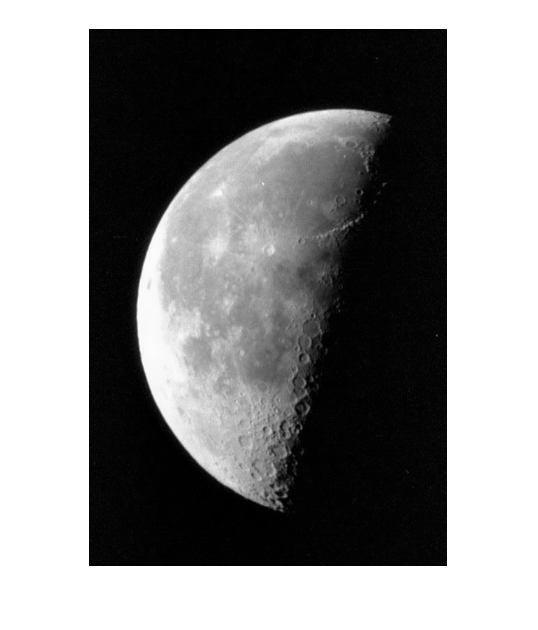

IM= imread('moon.tif');
imshow(IM);


Tmin= 60

Tmin = 60

Tmax= 140

Tmax = 140

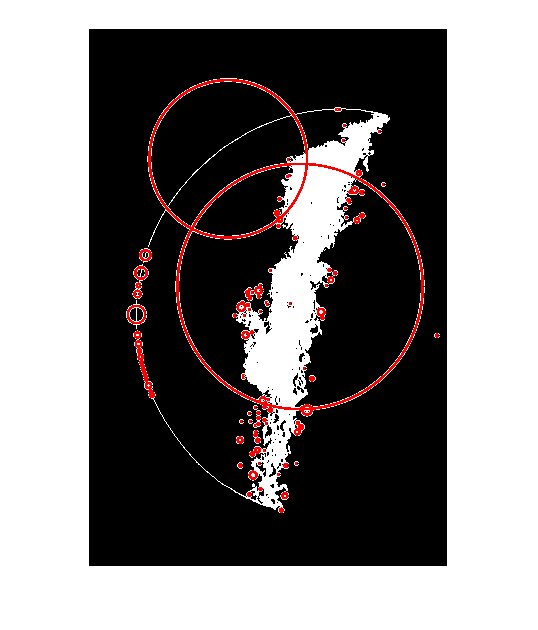


J= (IM >Tmin & IM < Tmax); %%Given upper and lower treshhold shows the craters in the best way
imshow(J)

moonbin=imbinarize(uint8(J));

stats = regionprops('table', moonbin,'Centroid', 'MajorAxisLength','MinorAxisLength');

centers = stats.Centroid;
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;

viscircles(centers,radii);